**Моделирование продолжительностью 5 секунд, с параметрами колебаний вокруг нижней точки равновесия и с параметрами колебаний вокруг верхней точки равновесия**

## Колебания в нижней точке


decrement = 0; % b
frequency = 0.1; % w
amplitude = 0.1; % A
lenght = 1; % l
start_angle = 30; % theta
sim('kapitsa_pendulum.slx');

I = 1

x_down = coordX;
y_down = coordY;
theta_down = theta;
dtheta_down = dtheta;


## Колебания в верхней точке


decrement = 0; % b
frequency = 1; % w
amplitude = 0.1; % A
lenght = 1; % l
start_angle = 170; % theta
sim('kapitsa_pendulum.slx');

I = 1

x_up = coordX;
y_up = coordY;
%theta_up = theta;
%dtheta_up = dtheta;



## Графики

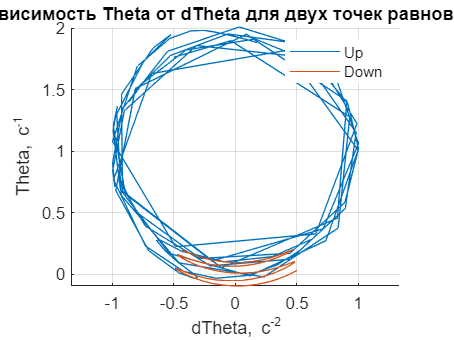

hold on;
plot(x_up, y_up);
hold all;
plot(x_down, y_down);
xlabel('X, м');
ylabel('Y, м');
grid on;
legend('Up','Down');
legend('boxoff');
title('Зависимость x от y для двух точек равновесия');
axis equal;
hold off;


%plot(dtheta_up, theta_up);
hold all;
%plot(dtheta_down, theta_down);
ylabel('Theta, c^{-1}');
xlabel('dTheta, c^{-2}');
legend('Up','Down')
legend('boxoff')
title('Зависимость Theta от dTheta для двух точек равновесия')
hold off;

## **Исследования различных режимов колебаний**

start_angle = 120;
frequency = 0.1;
sim('kapitsa_pendulum.slx');

I = 1

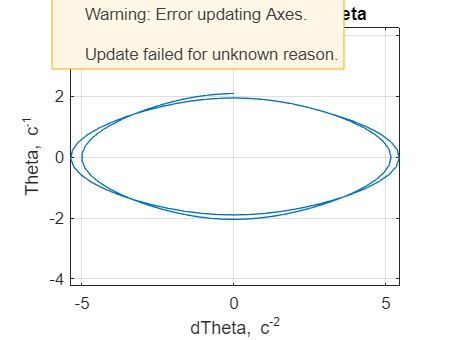

theta_120 = theta;
dtheta_120 = dtheta;

subplot()
plot(dtheta_120, theta_120);
axis equal;
ylabel('Theta, c^{-1}');
xlabel('dTheta, c^{-2}');
grid on;
title('Зависимость Theta от dTheta');

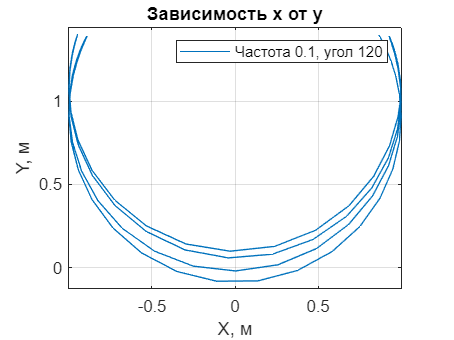


x = coordX;
y = coordY;


plot(x, y);
axis equal;
xlabel('X, м');
ylabel('Y, м');
grid on;
title('Зависимость x от y');
legend('Частота 0.1, угол 120');


frequency = 150;
sim('kapitsa_pendulum.slx');

I = 1

subplot(3,2,4);
plot(dtheta_120, theta_120);
axis equal;
ylabel('Theta, c^{-1}');
xlabel('dTheta, c^{-2}');
grid on;
title('Зависимость Theta от dTheta');

x = coordX;
y = coordY;

subplot(3,2,3);
plot(x, y);
axis equal;
xlabel('X, м');
ylabel('Y, м');
grid on;
title('Зависимость x от y');
legend('Частота 150, угол 120');

frequency = 200;
sim('kapitsa_pendulum.slx');

I = 1

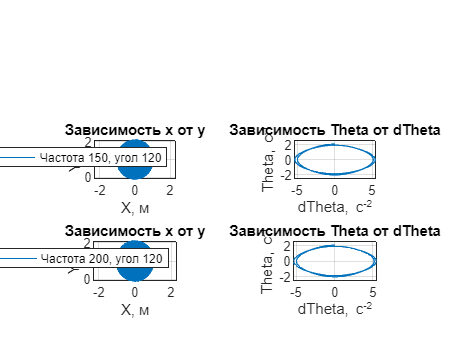

subplot(3,2,6);
plot(dtheta_120, theta_120);
axis equal;
ylabel('Theta, c^{-1}');
xlabel('dTheta, c^{-2}');
grid on;
title('Зависимость Theta от dTheta');

x = coordX;
y = coordY;

subplot(3,2,5);
plot(x, y);
axis equal;
xlabel('X, м');
ylabel('Y, м');
grid on;
title('Зависимость x от y');
legend('Частота 200, угол 120');

function research_tdt (p)
    sim('kapitsa_pendulum.slx');
   
    theta_120 = theta;
    dtheta_120 = dtheta;
    
    subplot(3,2,p);
    plot(dtheta_120, theta_120);
    axis equal;
    ylabel('Theta, c^{-1}');
    xlabel('dTheta, c^{-2}');
    grid on;
    title('Зависимость Theta от dTheta');
    

end

function research_xy (p)
    sim('kapitsa_pendulum.slx');
    x = coordX;
    y = coordY;
    
    subplot(3,2,p);
    plot(x, y);
    axis square;
    axis equal;
    xlabel('X, м');
    ylabel('Y, м');
    grid on;
    title('Зависимость x от y');
    
end


